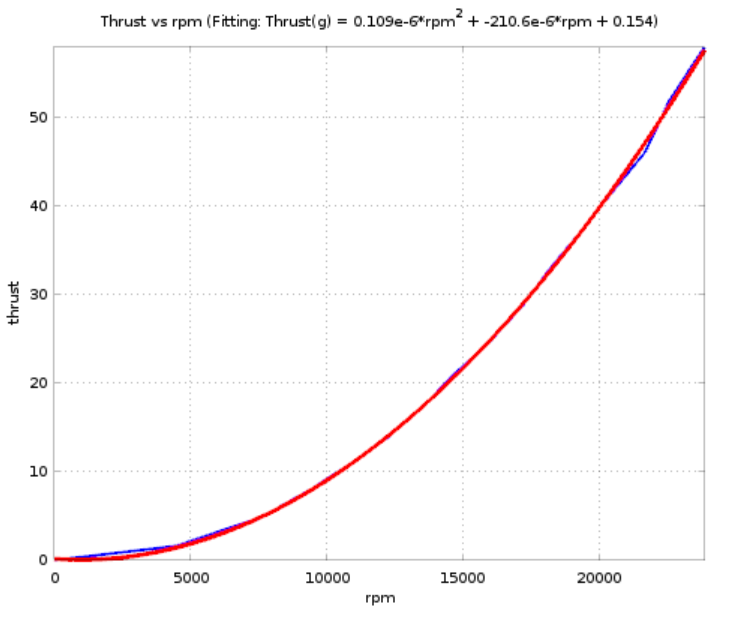

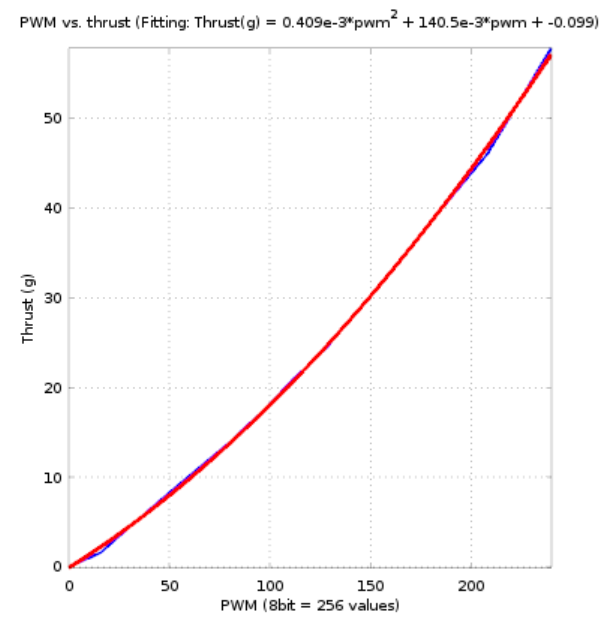

syms thrust pwm rpm 

pwm_to_thrust(pwm) = 0.409e-3*pwm^2 + 140.5e-3*pwm + (-0.099)

$$pwm\_to\_thrust(pwm) = \frac{7544718326147207\,{\mathrm{pwm}}^{2}}{18446744073709551616}+\frac{281\,\mathrm{pwm}}{2000}-\frac{99}{1000}$$



pwm16_to_thrust(pwm) = 0.409e-3*pwm^2 + 140.5e-3*pwm + (-0.099)

$$pwm16\_to\_thrust(pwm) = \frac{7544718326147207\,{\mathrm{pwm}}^{2}}{18446744073709551616}+\frac{281\,\mathrm{pwm}}{2000}-\frac{99}{1000}$$


syms x
solve(256*x == 65536,x)

$$ans = 256$$


256^2

ans = 65536


solve(thrust == pwm16_to_thrust(pwm/256),pwm)

$$ans = \left(\begin{array}{c} -\frac{604462909807314587353088\,\sqrt{\frac{7544718326147207\,\mathrm{thrust}}{302231454903657293676544}+\frac{11472845254943727195617}{37778931862957161709568000000}}}{7544718326147207}-\frac{41468280677699072032768}{943089790768400875}\\ \frac{604462909807314587353088\,\sqrt{\frac{7544718326147207\,\mathrm{thrust}}{302231454903657293676544}+\frac{11472845254943727195617}{37778931862957161709568000000}}}{7544718326147207}-\frac{41468280677699072032768}{943089790768400875} \end{array}\right)$$


thrust_to16bit(thrust) = 604462909807314587353088*sqrt((7544718326147207*thrust/302231454903657293676544 + 11472845254943727195617/37778931862957161709568000000))/7544718326147207 - 41468280677699072032768/943089790768400875

$$thrust\_to16bit(thrust) = \frac{604462909807314587353088\,\sqrt{\frac{7544718326147207\,\mathrm{thrust}}{302231454903657293676544}+\frac{717052828433983}{2361183241434822606848}}}{7544718326147207}-\frac{6043281514035325}{137438953472}$$


vpa(thrust_to16bit(35))

$$ans = 42963.207533420353261179637353275$$



fplot(pwm_to_thrust(pwm),[1 255])

tr(rpm) = 0.109e-6*rpm^2 + (-210.6e-6)*rpm+0.154

fplot(tr(rpm),[0 25000])


f1 = 0.409e-3*pwm^2 + 140.5e-3*pwm + (-0.099)
f2 = 0.109e-6*rpm^2 + (-210.6e-6)*rpm+0.154


eq1 = thrust == f1
eq2 = thrust == f2

rpm(thrust) = vpasolve(eq2,rpm)


rpm(2)

pwm2rpm = matlabFunction(rpm(f1))

pwm2rpm(20)


%solve(eq2,rpm)




fplot(rpm(f1),[0 255])


C_T = 0.055; 

    C_Q = 0.024
    
    air_density = 1.293; %kg/m^3
    
    propeller_radius = 0.045/2; %m
     
    disc_area = pi*propeller_radius^2% - pi*0.002^2

syms rpm 


thrust_from_rpm(rpm) = air_density*C_T*disc_area*propeller_radius^2*(rpm*0.1047198)^2

round(thrust_from_rpm(20000),5)

round((tr(20000)*0.001*9.82)/4,5)

fplot(thrust_from_rpm(rpm),[0 25000])
hold on 
fplot(tr(rpm)*0.001*9.82*0.25,[0 25000])
hold off 


rpm2torque(rpm) = air_density * C_Q * disc_area * propeller_radius^3 * (rpm*0.1047198)^2

round(rpm2torque(20000),5)


thrust=0.1

%4587155.9633027524343181985892006*sqrt(0.00000043599999999999998662292386049366*thrust - 0.000000022791639999999999545786972133393)x+966.05504587155964517853530406993; 

